# コマンド早見表

系統モデルの定義から近似線形化まで、よく使うコマンドを一つにまとめています。それぞれの詳しい説明は、目次（`GUILDA.tutorial()`）から開ける Step1〜12 にあります。

**注意:** GUILDA を起動してから（`>> GUILDA`）実行してください。

## 同梱の系統を読み込む

同梱の系統は `network.` に続けて名前を書くだけで読み込めます（Step 1）。

net = network.IEEE9bus();
net68 = network.IEEE68bus();

## 系統モデルを組み立てる

空の系統（`PowerNetwork`）に、母線・ブランチ・機器の順に加えます。Slack 母線は、機器を付けた母線で指定します（Step 1、Step 2）。

net = PowerNetwork("Test");
b1 = net.add_bus(V=1.0, Varg=0);
b2 = net.add_bus();
net.add_branch("pi", [1, 2], R=0.01, X=0.085, C=0.088);
gen = b1.add_component("gen-1axis", parameter="NGT6");
b1.l_isSlack = true;

INFO: ' B001 '  set as slack bus.
      P and Q specifications for ' B001SG1 ' ignored in powerflow calculation.


ld = b2.add_component("load-power", P=-0.5, Q=-0.1);

## 潮流計算と平衡点

潮流計算の結果は `ResultPF` で返ります。`initialize` は潮流計算の解から各機器の平衡点を求めます（Step 4）。

pf = net.calculate_powerflow();
net.initialize();

## 制御器を付ける

ローカル制御器は機器に、グローバル制御器は系統に付けます。付け外しの後は `initialize` をやり直します（Step 2）。

avr = gen.add_local_controller("avr-ST1");
net.initialize();

グローバル制御器（AGC）の例:

net9 = network.IEEE9bus();
agc = net9.add_global_controller("agc-PI", ["B001SG1", "B002SG1"]);

INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1; Pmech_B002SG1_PowerNetworkAGC1 -> Pmech_B002SG1.


net9.initialize();

## 時間シミュレーション

外乱はシナリオに入れ、シナリオのタグを指定して実行します（Step 5、Step 6）。

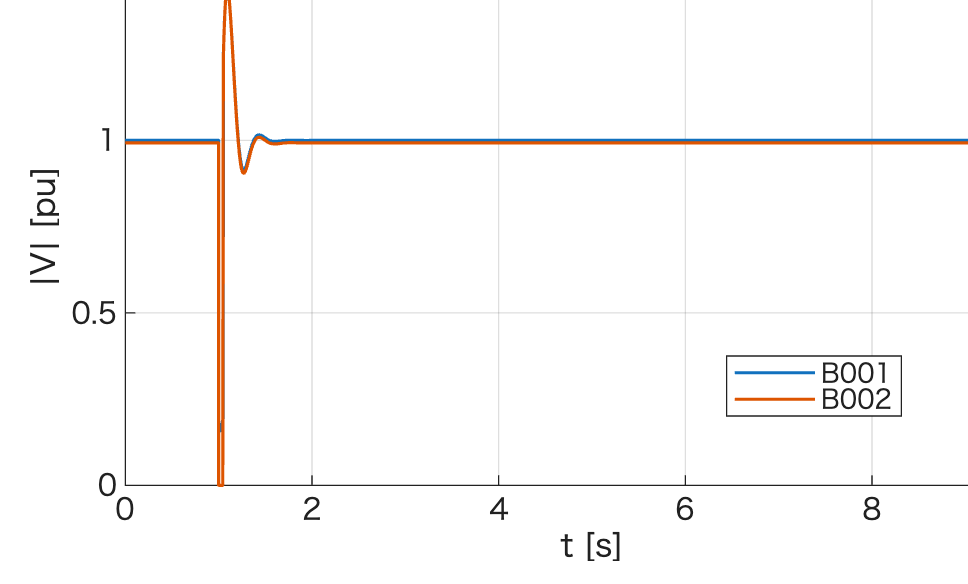

sc = net.add_scenario("fault", Time=[0, 10]);
sc.add_fault("B002", [1, 1.05]);
res = net.simulate("fault");
G = res.plot_trajectory();

## 近似線形化

平衡点のまわりで線形化した $E\dot{x} = Ax + Bu, y = Cx + Du$ の行列を返します（Step 8）。

sys = net.get_sys();
eig(sys.A)

ans =  -10.0000 + 0.0000i
  -0.0000 + 0.0000i
  -3.8445 + 0.0000i
   1.0864 + 2.7416i
   1.0864 - 2.7416i
  -1.0000 + 0.0000i


## そのほかの解析

- 最適潮流計算: `net.calculate_optimal_powerflow()`（Step 9）

- 連続潮流計算: `net.calculate_continuation_powerflow(LoadBus=["B005","B006","B008"])`（Step 10）

- 設定: `GUILDA.setting`、`GUILDA.config`（Step 11）

- 書き出しと読み込み: `net.export(folder)`、`PowerNetwork.import(folder)`（Step 12）